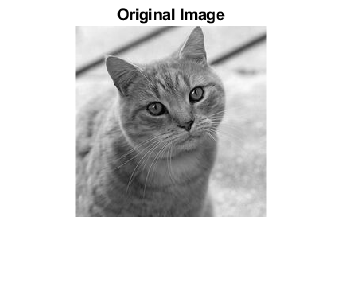

%% Image Interpolation Using Nearest neighbor technique

g=imread("im004.jpg");
% by imread command we can read the image in the form of 2-D array.
g=im2gray(g);
% converting colour Image to grayscale image
[r c]=size(g);
% taking the size of image or array

t=[];
% creating an array which will be used as final outpout of image.

temp=1;
% first temperory variable for visiting array elements

gemp=1;
% second temperory variable for visiting array elements

for i=1:1:r

    for j=1:1:c

        t(temp,gemp)=g(i,j);  % Up sampling

        gemp=gemp+3;

    end

    temp=temp+3;

    gemp=1;

end

img_resized=uint8(t);
% storing the Upsampled image in new variable

figure;

imshow(g);
title('Original Image')
% displaying the Original Image

truesize

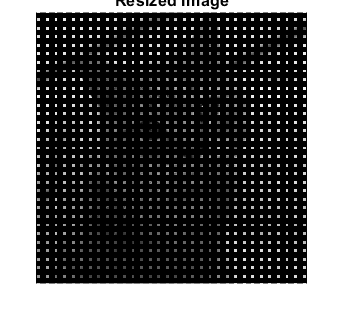


figure;

imshow(img_resized)
title('Resized Image')
% Displaying the Upsampled image


truesize

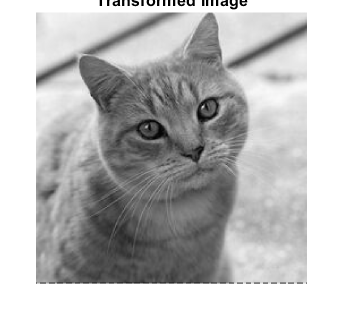


[R C] = size(t);

for i=1:3:(R-1)  % applying the Bilinear Interpolation Technique

    for j=1:3:(C-1)

        for a=1:1:2
               
            t(i,j+a)=(1-a/3)*t(i,j) + (a/3)*t(i,j+3); % calculating the weighted sum by the nearest two pixels for row unknown pixel


        end    

    end

end 

for j=1:1:(C-1)

    for i=1:3:(R-1)

        for a=1:1:2
               
            t(i+a,j)=(1-a/3)*t(i,j) + (a/3)*t(i+3,j); % calculating the weighted sum by the nearest two pixels for columns unknown pixel


        end    

    end

end

img_resized1=uint8(t);
% Storing the Transformed Image


figure;

imshow(img_resized1)
title('Transformed Image')
% Displaying the Tranformed image

truesize